% TPN4 Balbona Delfina

clear
clc
load('5MW.mat')


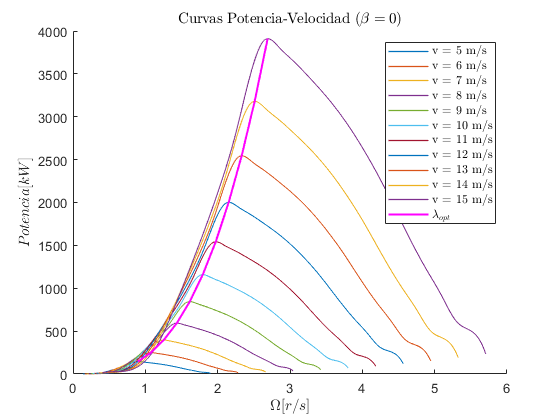

% Ejercicio 1
% Representacion de las curvas características de par y potencia de la
% turbina en función de la velocidad de rotación para diferentes 
% velocidades de viento.

v = 5:1:15;
w_max_vals = [];
P_max_vals = [];
R = 36.8000;
rho = 1.2200;
A = pi * (R^2);

figure(1)
hold on 
for i = 1:11
    P = (0.5 * rho * A *(v(i)^3).*Cp_table(1,:))/1000;
    omega_r = tsr_axis.*v(i)/R;
    
    % Interpolación spline
    omega_r_dense = linspace(min(omega_r), max(omega_r), 500); % Densidad alta
    P_dense = spline(omega_r, P, omega_r_dense); % Interpolar con spline
    
    % Graficar curvas suavizadas
    plot(omega_r_dense, P_dense, 'LineWidth', 1);
    
    [P_max, idx_max] = max(P_dense);
    w_max = omega_r_dense(idx_max);
    w_max_vals = [w_max_vals, w_max];
    P_max_vals = [P_max_vals, P_max];
   
end 

plot(w_max_vals, P_max_vals, 'm', 'LineWidth', 1.5);
legend('v = 5 m/s','v = 6 m/s', 'v = 7 m/s', 'v = 8 m/s','v = 9 m/s', 'v = 10 m/s', 'v = 11 m/s', 'v = 12 m/s', 'v = 13 m/s', 'v = 14 m/s', 'v = 15 m/s', '$\lambda_{opt}$','Interpreter', 'latex')

title('Curvas Potencia-Velocidad ($\beta = 0$)','Interpreter', 'latex')
xlabel('$\Omega [r/s]$','Interpreter', 'latex');
ylabel('$Potencia [kW]$','Interpreter', 'latex');
hold off

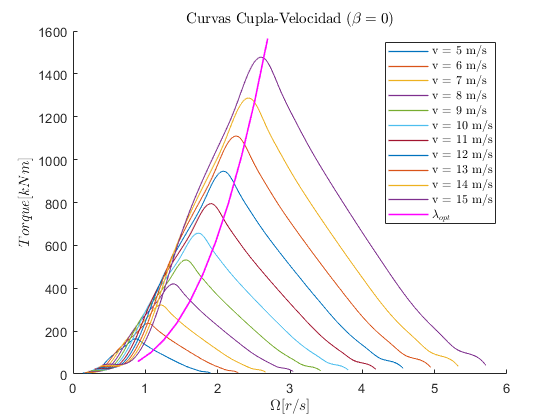


w_max_vals = [];
P_max_vals = [];

figure(2)
hold on 
for i = 1:11
    P = (0.5 * rho * A *(v(i)^3).*Cp_table(1,:))/1000;
    omega_r = tsr_axis.*v(i)/R;
    tau = P ./ omega_r; % Cupla mecánica
    
    % Interpolación spline
    omega_r_dense = linspace(min(omega_r), max(omega_r), 500); % Densidad alta
    tau_dense = spline(omega_r, tau, omega_r_dense); % Interpolar con spline
    P_dense = spline(omega_r, P, omega_r_dense); % Interpolar con spline

    % Graficar curvas suavizadas
    plot(omega_r_dense, tau_dense, 'LineWidth', 1);
    
    [P_max, idx_max] = max(P_dense*18/45);
    w_max = omega_r_dense(idx_max);
    w_max_vals = [w_max_vals, w_max];
    P_max_vals = [P_max_vals, P_max];
   
end 

plot(w_max_vals, P_max_vals, 'm', 'LineWidth', 1.2);
legend('v = 5 m/s','v = 6 m/s', 'v = 7 m/s', 'v = 8 m/s','v = 9 m/s', 'v = 10 m/s', 'v = 11 m/s', 'v = 12 m/s', 'v = 13 m/s', 'v = 14 m/s', 'v = 15 m/s', '$\lambda_{opt}$','Interpreter', 'latex')

title('Curvas Cupla-Velocidad ($\beta = 0$)','Interpreter', 'latex')
xlabel('$\Omega [r/s]$','Interpreter', 'latex');
ylabel('$Torque [kNm]$','Interpreter', 'latex');
hold off 

% Ejercicio 2
% Diseño del valor de la relación de engranajes Nv para que el sistema
% realice una limitación de potencia pasiva (control por frente de stall) a 5MW



